# 4.7 Design a SS controller selecting the poles using the LQR technique

load Linear_Param.mat
Cweight = [0 0 16 0]; %Most weight on theta_b, then on x_w, least on velocities
B1 = B(:,1);
[num,den] = ss2tf(A,B1,Cweight,0)

num =             0            0  -1.4404e+03   3.4361e-07   5.0577e-13


den =    1.0000e+00   4.7501e+02  -6.2019e+01  -1.5371e+04            0


s = tf("s");
Nplus = num(1)*(s)^4 +num(2)*(s)^3 +num(3)*(s)^2 +num(4)*(s)^1 +num(5)*(s)^0;
Nminus = num(1)*(-s)^4 +num(2)*(-s)^3 +num(3)*(-s)^2 +num(4)*(-s)^1 +num(5)*(-s)^0;
Dplus = den(1)*(s)^4 +den(2)*(s)^3 +den(3)*(s)^2 +den(4)*(s)^1 +den(5)*(s)^0;
Dminus = den(1)*(-s)^4 +den(2)*(-s)^3 +den(3)*(-s)^2 +den(4)*(-s)^1 +den(5)*(-s)^0;
sysGG = Nplus*Nminus/(Dplus*Dminus)

sysGG =
 
      2.075e06 s^4 - 1.457e-09 s^2 + 2.558e-25
  ------------------------------------------------
  s^8 - 2.258e05 s^6 + 1.461e07 s^4 - 2.363e08 s^2
 
Continuous-time transfer function.
Model Properties


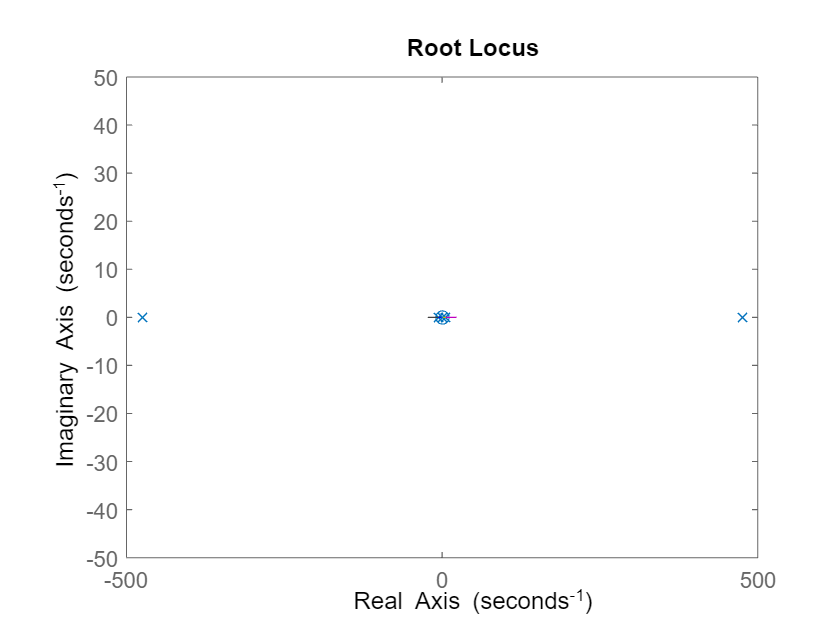

rho = linspace(0,50,200);
rlocus(sysGG,rho)

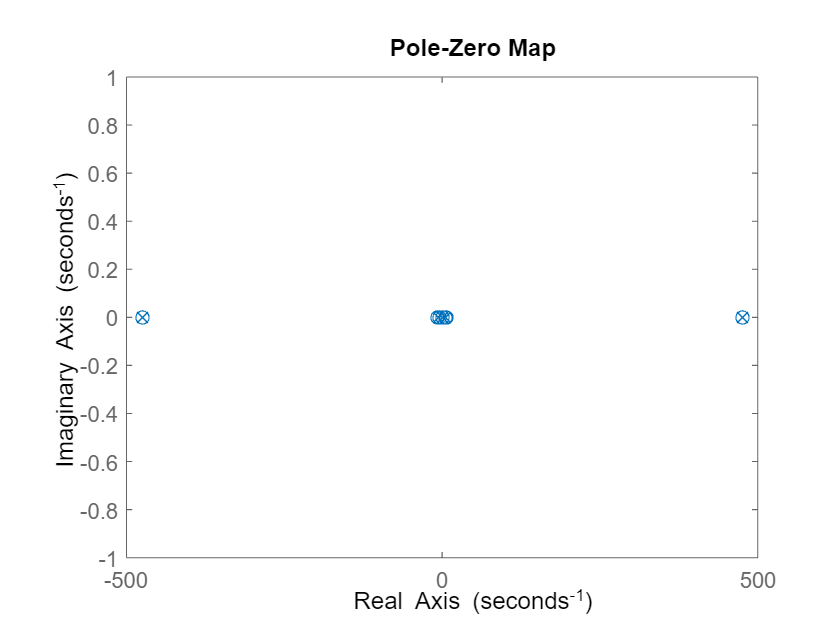


rhoChose = 0.5;
  pzmap(1+rhoChose*sysGG)

poles =  zero(1+rhoChose*sysGG);
format shortE
stablePoles = poles(real(poles)<0)

stablePoles =   -4.7506e+02
  -6.8610e+00
  -4.7159e+00
  -2.3266e-17


K = acker(A,B1,stablePoles)

K =   -4.9192e-16  -4.2286e+01  -6.2139e+01  -9.7937e+00


poles = stablePoles;
save("poles.mat","poles")